# Exam 2 Directory - [Move]

This is a good starting point for exam 2 content. It gives an example of everything needed to run all the main functions we talked about. A good strat is using the help menu to access format

## Ch 13 - Eigenvalues

[A-lamda*I]{x} = 0 -> det(A-lamda*I) -> find lamda

Applicable to 2nd order diff eqs.

help eig

 eig    Eigenvalues and eigenvectors.
    E = eig(A) produces a column vector E containing the eigenvalues of 
    a square matrix A.
 
    [V,D] = eig(A) produces a diagonal matrix D of eigenvalues and 
    a full matrix V whose columns are the corresponding eigenvectors  
    so that A*V = V*D.
  
    [V,D,W] = eig(A) also produces a full matrix W whose columns are the
    corresponding left eigenvectors so that W'*A = D*W'.
 
    [...] = eig(A,"nobalance") performs the computation with balancing
    disabled, which sometimes gives more accurate results for certain
    problems with unusual scaling. If A is symmetric, eig(A,"nobalance")
    is ignored since A is already balanced.
 
    [...] = eig(A,"balance") is the same as eig(A).
 
    E = eig(A,B) produces a column vector E containing the generalized 
    eigenvalues of square ma

help powereig

  powereig - Computes the dominant eigenvalue and eigenvector using the Power Method
 
  Syntax:
    [eigval, eigvect] = powereig(A, es, maxit)
 
  Inputs:
    A     - Square matrix for which the dominant eigenvalue/vector is sought
    es    - Desired relative error tolerance (stopping criterion, e.g. 0.0001)
    maxit - Maximum number of iterations to perform
 
  Outputs:
    eigval  - Dominant (largest magnitude) eigenvalue of A
    eigvect - Corresponding normalized eigenvector
 
  Example:
    A = [4 1; 2 3];
    [eigval, eigvect] = powereig(A, 0.0001, 100)
 
  Description:
    This function implements the Power Method, an iterative algorithm used 
    to find the largest eigenvalue (in magnitude) and its associated eigenvector.
    The algorithm repeatedly multiplies an arbitrary vector by the matrix A,
    normalizes the result, and estimates convergence based on the change in eigenvalue.
 
  Note: Finding the smallest eigenvalue
    The smallest eigenvalue and its associated ei

help solve_ode_system

  ANALYZE_ODE_SYSTEM_VARIABLES Solves a 2x2 linear system x' = Ax.
    This function calculates the eigenvalues and eigenvectors, classifies the 
    system type (e.g., Undamped, Overdamped), and generates the final 
    symbolic displacement equation y(t) = x1(t).
    function [y_eq, type, evals, v1, v2] = solve_ode_system(A)
 
  Inputs:
    A: The 2x2 coefficient matrix [0 1; -k/m -c/m]
 
  Outputs:
    system_type: Classification string (e.g., 'Pure Oscillation (Undamped)')
    evals_str:   Formatted string of the two eigenvalues (L1 and L2)
    evec1_str:   Formatted string of the first eigenvector (v1)
    evec2_str:   Formatted string of the second eigenvector (v2)
    y_eq_str:    Symbolic equation for the displacement y(t)




A = [10 -5; -5 10];
[v,lamda] = eig(A) % v = eigenvectors (lamda plugged in -> set = 0)

v =    -0.7071   -0.7071
   -0.7071    0.7071


lamda =      5     0
     0    15



% Needs work:
%   - Setting up the matrixes from the diff eq
%       * x1 = y, x2 = y' = x1', x3 = y'' = x2', x4 = y''' = x3'
%       * x1' = x2; x2' = x3, x3' = [solve for y''' (or the largest)]
%       * x' = A*x form
%       * A = [0 1 0; 0 0 1; # # #]

% Example
%   y''' - 4y'' + 6y' - 3y = 0
%       * x1 = y, x1' = x2 = y', x2' = x3 = y'', x3' = x4 = y'''
%       * x3' = 4x3 - 6x2 + 3x1
%       * x' = A*x, x = [x1 x2 x3]'
B = [0 1 0; 0 0 1; 3 -6 4]; % go up from x1 to x3 to match x vector
[v1,lamda1] = eig(B)

v1 =   -0.5774 + 0.0000i   0.1387 - 0.2402i   0.1387 + 0.2402i
  -0.5774 + 0.0000i   0.4160 - 0.2402i   0.4160 + 0.2402i
  -0.5774 + 0.0000i   0.8321 + 0.0000i   0.8321 + 0.0000i


lamda1 =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.5000 + 0.8660i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.5000 - 0.8660i



% Powereig
es = 0.001; 
[eigval, eigvect] = powereig(B, es)

eigval = 1

eigvect =      1
     1
     1


% normalized eigenvector bc the highest one always set to 1

% we can normalize v1 to doublecheck
Vnorm = v1./max(v1)

Vnorm =    1.0000 + 0.0000i   0.1667 - 0.2887i   0.1667 + 0.2887i
   1.0000 + 0.0000i   0.5000 - 0.2887i   0.5000 + 0.2887i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i



% Find the smallest eigenvector
[eigvalSmall, eigvectSmall] = powereig(inv(B), es)

eigvalSmall = 1

eigvectSmall =      1
     1
     1




% Polynomial method -> characteristic equation
%   Wild, not sure how it works fully
%   Uses the characteristic polynomial
help poly

 poly Convert roots to polynomial.
    poly(A), when A is an N by N matrix, is a row vector with
    N+1 elements which are the coefficients of the
    characteristic polynomial, det(lambda*eye(size(A)) - A).
 
    poly(V), when V is a vector, is a vector whose elements are
    the coefficients of the polynomial whose roots are the
    elements of V. For vectors, ROOTS and poly are inverse
    functions of each other, up to ordering, scaling, and
    roundoff error.
 
    Examples:
 
    roots(poly(1:20)) generates Wilkinson's famous example.
 
    Class support for inputs A,V:
       float: double, single
 
    See also roots, conv, residue, polyval.

    Documentation for poly
    

p = poly(B) % when A is square, poly(A) = coefficients of characteristic poly

p =     1.0000   -4.0000    6.0000   -3.0000


%           aka coeff of det(lamda*eye(size(A)-A)
d = roots(p) % eigenvalues based off the characteristic polynomial

d =    1.5000 + 0.8660i
   1.5000 - 0.8660i
   1.0000 + 0.0000i



% solve_ode_system
%   * Chat code designed to interpret stuff after A is found. Should do
%   everything. Prob don't use on the exam

## Ch 14 - Linear Regression

#### Stats Basics

help var

 var Variance.
    For vectors, Y = var(X) returns the variance of the values in X.  For
    matrices, Y is a row vector containing the variance of each column of
    X.  For N-D arrays, var operates along the first non-singleton
    dimension of X.
 
    var normalizes Y by N-1 if N>1, where N is the sample size.  This is
    an unbiased estimator of the variance of the population from which X is
    drawn, as long as X consists of independent, identically distributed
    samples. For N=1, Y is normalized by N. 
 
    Y = var(X,1) normalizes by N and produces the second moment of the
    sample about its mean.  var(X,0) is the same as var(X).
 
    Y = var(X,W) computes the variance using the weight vector W.  W 
    typically contains either counts or inverse variances.  The length of W 
    must equal the length of the dimension over which v

help std

 std Standard deviation.
    For vectors, Y = std(X) returns the standard deviation.  For matrices,
    Y is a row vector containing the standard deviation of each column.  For
    N-D arrays, std operates along the first non-singleton dimension of X.
 
    std normalizes Y by N-1 if N>1, where N is the sample size.  This is
    the sqrt of an unbiased estimator of the variance of the population
    from which X is drawn, as long as X consists of independent,
    identically distributed samples. For N=1, Y is normalized by N.
 
    Y = std(X,1) normalizes by N and produces the square root of the second
    moment of the sample about its mean.  std(X,0) is the same as std(X).
 
    Y = std(X,W) computes the standard deviation using the weight vector W.
    W typically contains either counts or inverse variances.  The length of
    W must equal the lengt

help hist

 hist  Histogram.
    hist is not recommended. Use HISTOGRAM or HISTCOUNTS instead.
  
    N = hist(Y) bins the elements of Y into 10 equally spaced containers
    and returns the number of elements in each container.  If Y is a
    matrix, hist works down the columns.
 
    N = hist(C) returns the category counts for the categorical array C.
    For a categorical matrix, hist works down the columns of Y and returns
    a matrix of counts with one column for each column of Y and one row for
    each category.
 
    N = hist(Y,M), where M is a scalar, uses M bins.
 
    N = hist(Y,X), where X is a vector, returns the distribution of Y among
    bins with centers specified by X. The first bin includes data between
    -inf and the first center and the last bin includes data between the
    last bin and inf. Note: Use HISTC if it is more natural to specif

help histcounts

 histcounts - Histogram bin counts
    This MATLAB function partitions the X values into bins and returns the
    bin counts and the bin edges.

    Syntax
      [N,edges] = histcounts(X)
      [N,edges] = histcounts(X,nbins)
      [N,edges] = histcounts(X,edges)
      [N,edges,bin] = histcounts(___)

      N = histcounts(C)
      N = histcounts(C,Categories)
      [N,Categories] = histcounts(___)

      [___] = histcounts(___,Name,Value)

    Input Arguments
      X - Data to distribute among bins
        vector | matrix | multidimensional array
      C - Categorical data
        categorical array
      


A = [29.65 28.55 28.65 30.15 29.35 29.75 29.25 ...
    30.65 28.15 29.85 29.05 30.25 30.85 28.75 ...
     29.65 30.45 29.15 30.45 33.65 29.35 29.75 ... 
     31.25 29.45 30.15 29.65 30.55 29.65 29.25]; % row vector best

mean_p = mean(A)

mean_p = 29.8321

med_p = median(A)

med_p = 29.6500

mod = mode(A)

mod = 29.6500

% [M,F] = mode(A) % FAILS if multimodal: only designed for having 1 mode - use hist instead
rang = range(A)

rang = 5.5000

rang_2 = max(A)-min(A)

rang_2 = 5.5000

stdDev = std(A)

stdDev = 1.0453

varA = var(A)

varA = 1.0926

cv = varA./mean_p*100 % percent

cv = 3.6626

s = size(A)

s =      1    28


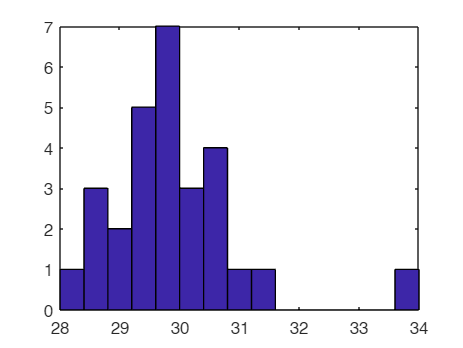


% histogram
binmids = [28.2:0.4:33.8];
figure;
hist(A,binmids) % no arguments, it makes a histogram

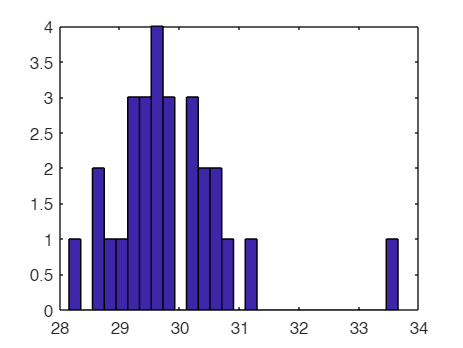

figure;
hist(A, s(2))
hold off;


[N,edges] = histcounts(A, s(2))

N =      1     0     2     1     1     3     3     4     3     0     3     2     2     1     0     1     0     0     0     0     0     0     0     0     0     0     0     1


edges =    28.1000   28.2990   28.4980   28.6970   28.8960   29.0950   29.2940   29.4930   29.6920   29.8910   30.0900   30.2890   30.4880   30.6870   30.8860   31.0850   31.2840   31.4830   31.6820   31.8810   32.0800   32.2790   32.4780   32.6770   32.8760   33.0750   33.2740   33.4730   33.6720


#### Linear Regression Basics

help linregr

  linregr: linear regression curve fitting
    [a, r2] = linregr(x,y): Least squares fit of straight
    line to data by solving the normal equations
  input:
    x = independent variable
    y = dependent variable
  output:
    a = vector of slope, a(1), and intercept, a(2)
    r2 = coefficient of determination
 
  linearization help:
    y = alph * exp(beta*x)
        ln(y) = ln(alph) + beta*x 
            Note: use log() in MATLAB
        [a, r2] = linregr(x, log(y));
        alpha = exp(a(2));
        beta  = a(1);
 
    y = alph * x^beta
        log10(y) = log10(alph) + beta*log10(x)
        [a, r2] = linregr(log10(x), log10(y));
        alpha = 10^(a(2));
        beta  = a(1);
 
    y = alph * x/(beta + x)
        1/y = 1/alph + (beta/alph)*(1/x)
          (linear in 1/x)
        [a, r2] = linregr(1./x, 1./y);
        alpha = 1 / a(2);
        beta  = a(1) / a(2);



help linregrzero

  linregrzero: linear regression curve fitting with zero intercept
  [a, r2] = linregr(x,y): Least squares fit of straight
  line to data with zero intercept
  input:
  x = independent variable
  y = dependent variable
  output:
  a1 = slope



help fitlm

 fitlm Create linear regression model by fitting to data.
    LM = fitlm(TBL) fits a linear model LM to the data in the table/dataset
    TBL, treating the last column as the response variable.
 
    LM = fitlm(TBL,Y) fits a linear model LM to the data in TBL, using Y as
    the response variable. Y must be a double or single vector with the
    same number of rows as TBL.
 
    LM = fitlm(TBL,VARNAME) fits a linear model LM to the data TBL, using
    the variable name given by VARNAME as the response variable. VARNAME 
    must be a string scalar or character vector of a variable in TBL.
 
    LM = fitlm(__,MODELSPEC) fits the model specified by MODELSPEC to
    variables in TBL, and returns the linear model LM. MODELSPEC can be any 
    of the following:
 
        'linear'            Linear (main effect) terms only.
        'interactions'      Linear and pairwise interaction terms.
        'purequadr

help polyfit

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains these fields:
 
          R  -  Triangular R factor (possibly permuted) from a QR
                decomposition of the Vandermonde matrix of X
         df  -  Degrees of freedom
      normr  -  Norm of the residuals
    rsquared -  Coefficient of determination or (unadjusted) R-squared
 
    If the data Y are random, an estimate of the covariance matrix of P is
    (Rinv*Rinv')*normr^2/df, where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit

help polyval

 polyval Evaluate polynomial.
    Y = polyval(P,X) returns the value of a polynomial P evaluated at X. P
    is a vector of length N+1 whose elements are the coefficients of the
    polynomial in descending powers:
 
        Y = P(1)*X^N + P(2)*X^(N-1) + ... + P(N)*X + P(N+1)
 
    The polynomial P is evaluated at all points in X. See POLYVALM for
    evaluation of a polynomial P in a matrix sense.
 
    [Y,DELTA] = polyval(P,X,S) uses the optional output structure S created
    by POLYFIT to generate prediction error estimates DELTA. DELTA is an
    estimate of the standard deviation of the error in predicting a future
    observation at X by P(X).
 
    If the coefficients in P are least squares estimates computed by
    POLYFIT, and the errors in the data input to POLYFIT are independent,
    normal, with constant variance, then Y +/- DELTA will contain at least
    50% of future observations at X.
 
    Y = polyval

#### Transformations

x = (0:0.5:5)';                 
y = 2.5 * exp(0.4 * x)+ 0.2*cos(x); % just added a slight jitter

figure;
[badFit_a badFit_r2] = linregr(x,y) % clearly doesn't look linear

badFit_a =     3.0034    0.7069


badFit_r2 = 0.9168

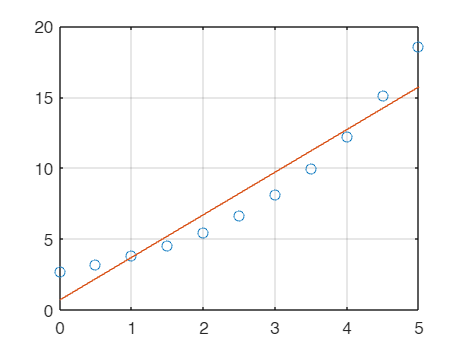

hold off;


% linearize **** y = alph*exp(beta*x)
figure;
[a, r2] = linregr(x,log(y))

a =     0.3859    0.9581


r2 = 0.9986

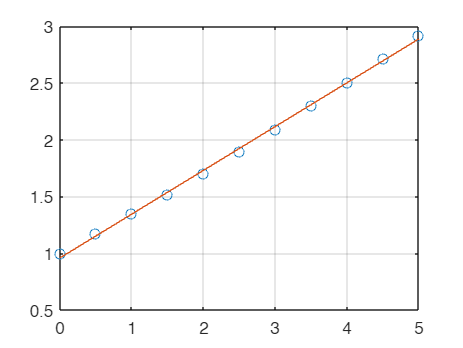

hold off;

alph = exp(a(2))

alph = 2.6067

beta = a(1)

beta = 0.3859

yp = alph*exp(beta*x);
plot(x,y,'o'); hold on;
plot(x,yp,'x');

% polyfit method (wait, n = 1 = a better example for lin)
x = 0:0.1:5;
y = x.^3 + sin(x).*cos(x);
p = polyfit(x,y,3) % 3rd order polynomial, n = 3

p =     0.9662    0.3183   -0.8450    0.5971


yfit = polyval(p,x) % remake the vector

yfit =     0.5971    0.5168    0.4486    0.3984    0.3719    0.3750    0.4134    0.4930    0.6195    0.7988    1.0366    1.3388    1.7111    2.1593    2.6893    3.3068    4.0176    4.8275    5.7424    6.7680    7.9101    9.1745   10.5670   12.0935   13.7596   15.5712   17.5342   19.6542   21.9372   24.3888   27.0149   29.8213   32.8138   35.9982   39.3803   42.9658   46.7606   50.7705   55.0013   59.4587   64.1486   69.0767   74.2489   79.6710   85.3487   91.2879   97.4943  103.9738  110.7321  117.7751


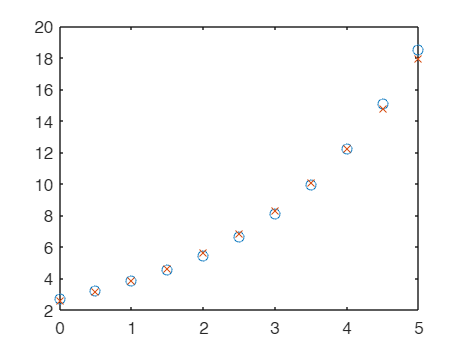

hold off;

figure;
plot(x,y,'go'); hold on;
plot(x,yfit,'bx')
hold off;
y15 = polyval(p,1.5) % value of y at x = 1.5

y15 = 3.3068

y_true = 1.5^3+ sin(1.5).*cos(1.5)

y_true = 3.4456



% linregrzero (no beta0)
x = [2, 4, 6, 7, 10, 11, 14, 17, 20];
y = [4, 5, 6, 5, 8, 8, 6, 9, 12];
help linregr

  linregr: linear regression curve fitting
    [a, r2] = linregr(x,y): Least squares fit of straight
    line to data by solving the normal equations
  input:
    x = independent variable
    y = dependent variable
  output:
    a = vector of slope, a(1), and intercept, a(2)
    r2 = coefficient of determination
 
  linearization help:
    y = alph * exp(beta*x)
        ln(y) = ln(alph) + beta*x 
            Note: use log() in MATLAB
        [a, r2] = linregr(x, log(y));
        alpha = exp(a(2));
        beta  = a(1);
 
    y = alph * x^beta
        log10(y) = log10(alph) + beta*log10(x)
        [a, r2] = linregr(log10(x), log10(y));
        alpha = 10^(a(2));
        beta  = a(1);
 
    y = alph * x/(beta + x)
        1/y = 1/alph + (beta/alph)*(1/x)
          (linear in 1/x)
        [a, r2] = linregr(1./x, 1./y);
        alpha = 1 / a(2);
        beta  = a(1) / a(2);



a1 = linregrzero(x,y) % just slope if no offset

a1 = 0.6144

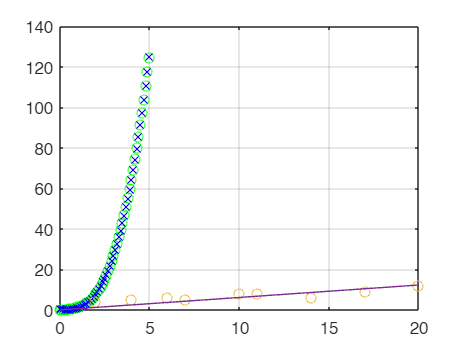

hold off;

coefficients = polyfit(x, y, 1) % used for slopes and intercepts, built-in

coefficients =     0.3678    3.2807


## Ch 15 - Nonlinear Regression

help fitnlm

 fitnlm Create nonlinear regression model by fitting to data.
    NLM = fitnlm(DS,MODELFUN,BETA0) fits the model specified by MODELFUN to
    variables in the dataset/table array DS, and returns the nonlinear model NLM.
    The coefficients are estimated using an iterative procedure starting
    from the initial values in the vector BETA0.
 
    MODELFUN can be either of the following:
 
      1. A function, specified using @, that accepts two arguments, a
         coefficient vector and an array of predictor values, and computes
         a vector of Y values. 
      2. A text string, such as 'y ~ b0+b1*sin(b2*X)', defining the
         response and a mathematical expression for the function. Symbols
         in the function expression that match variable names in the
         dataset/table are taken to be predictors, and the others are
         coefficients to be estimated.
 
    NLM = fitnlm(X,Y,MODELFUN,BETA0) fits a nonlinear regre

help fSSR

 fSSR: f = fSSR(a,xm,ym)
  F = a0*v^a1
  a(1) = a0, a(2) = a1
  sum of squares



help lsqcurvefit

 lsqcurvefit solves non-linear least squares problems.
    lsqcurvefit attempts to solve problems of the form:
    min  sum {(FUN(X,XDATA)-YDATA).^2}  where X, XDATA, YDATA and the values returned
     X                                  by FUN can be vectors or matrices.
    subject to:  A*X  <= B, Aeq*X  = Beq (linear constraints)
                 C(X) <= 0, Ceq(X) = 0  (nonlinear constraints)
                 LB <= X <= UB  (bounds)
 
    lsqcurvefit implements three different algorithms: trust region reflective,
    Levenberg-Marquardt, and Interior-Point. Choose one via the option Algorithm: for
    instance, to  choose Levenberg-Marquardt, set
    OPTIONS = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt'),
    and then pass OPTIONS to lsqcurvefit.
 
    X = lsqcurvefit(FUN,X0,XDATA,YDATA) starts at X0 and finds coefficients
    X to best fit the nonlinear functions in FUN to the data 

help polyfit

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains these fields:
 
          R  -  Triangular R factor (possibly permuted) from a QR
                decomposition of the Vandermonde matrix of X
         df  -  Degrees of freedom
      normr  -  Norm of the residuals
    rsquared -  Coefficient of determination or (unadjusted) R-squared
 
    If the data Y are random, an estimate of the covariance matrix of P is
    (Rinv*Rinv')*normr^2/df, where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit

#### Book Method

 v = [1 2 3 4 5];
 F = [2.1 4.5 7.9 12.6 19.3];

 a = fminsearch(@fSSR, [1 1], [], v, F)

a =     1.3505    1.6404


 %   [1 1] is an initial guess for [a0, a1], [] is a placeholder for options


#### Book Method 2 (Prob not that important)

% Polynomial Regression Using the Normal Equation
%
% This section fits a cubic polynomial to the data using ordinary least
% squares (OLS). Although the model is nonlinear in x (because of x^2 and 
% x^3), it is linear in the coefficients, so it can be solved using linear 
% regression methods.
%
% MODEL:
%     y = a0 + a1*x + a2*x^2 + a3*x^3
%
% DESIGN MATRIX (Z):
%     Each column of Z contains a different power of x:
%         Z = [ 1   x   x.^2   x.^3 ]
%     This allows the polynomial to be written in matrix form:
%         y = Z * a
%     where a = [a0; a1; a2; a3] contains the polynomial coefficients.
%
% NORMAL EQUATION:
%     The least-squares solution minimizes the squared error between the 
%     measured data (y) and the fitted curve (Z*a). The optimal coefficients 
%     are obtained using the normal equation:
%         a = (Z' * Z) \ (Z' * y)
%
% COEFFICIENT OF DETERMINATION (r^2):
%     r^2 measures how well the polynomial fits the data and is computed as:
%         r^2 = 1 - (Sr / St)
%     where Sr is the residual sum of squares and St is the total variation.
%
% After computing the coefficients, the fitted cubic curve can be evaluated
% using:
%     y_fit = a0 + a1*x + a2*x.^2 + a3*x.^3
%
% This method is equivalent to MATLAB's polyfit(x,y,3), but written out
% explicitly to show the underlying linear algebra.
% ======================================================================
x = [1 2 3 4 5]';
y = [2.1 4.5 7.9 12.6 19.3]';

Z = [ones(size(x)) x x.^2 x.^3] % cubic fit

Z =      1     1     1     1
     1     2     4     8
     1     3     9    27
     1     4    16    64
     1     5    25   125


a = (Z'*Z)\(Z'*y)

a =     0.0800
    1.9738
   -0.0429
    0.0833


Sr = sum((y-Z*a).^2)

Sr = 0.0023

r2 = 1-Sr/sum((y-mean(y)).^2)

r2 = 1.0000


% go down the column vector
0.08 + 1.97*x - 0.0429*x.^2 + 0.0833*x.^3

ans =     2.0904
    4.5148
    7.8530
   12.6048
   19.2700


#### Built-In Method (Important)***

% fitnlm
 v = [1 2 3 4 5];
 F = [2.1 4.5 7.9 12.6 19.3];

% Define model: F = a1 * v^a2
modelfun = @(b,x) b(1) * x.^b(2);

beta0 = [1 1];
nlm = fitnlm(v,F,modelfun,beta0)

nlm = Nonlinear regression model:
    y ~ b1*x^b2

Estimated Coefficients:
          Estimate      SE       tStat       pValue  
          ________    _______    ______    __________

    b1     1.3505     0.21788    6.1986     0.0084592
    b2     1.6404     0.10913    15.031    0.00063916


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 0.617
R-Squared: 0.994,  Adjusted R-Squared 0.992
F-statistic vs. zero model: 809, p-value = 7.95e-05


% lsqcurvefit
model = @(b,x) b(1) * x.^b(2);
b0 = [1 1];
a_fit = lsqcurvefit(model,b0,v,F)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


a_fit =     1.3505    1.6404


#### Polynomial Nonlinear Fit

% Find r^2 for nonlinear model, parabolic fit
v = [10, 20, 30, 40, 50, 60, 70, 80];
F = [25, 70, 380, 550, 610, 1220, 830, 1450];

% Polyfit
help polyfit

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains these fields:
 
          R  -  Triangular R factor (possibly permuted) from a QR
                decomposition of the Vandermonde matrix of X
         df  -  Degrees of freedom
      normr  -  Norm of the residuals
    rsquared -  Coefficient of determination or (unadjusted) R-squared
 
    If the data Y are random, an estimate of the covariance matrix of P is
    (Rinv*Rinv')*normr^2/df, where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit

[p,s] = polyfit(v, F, 2)     % quadratic fit

p =     0.0372   16.1220 -178.4821


s = struct with fields:
           R: [3×3 double]
          df: 5
       normr: 462.3776
    rsquared: 0.8818


F_pred = polyval(p, v)   % predicted values

F_pred = 1.0e+03 *

   -0.0135    0.1588    0.3387    0.5259    0.7206    0.9228    1.1324    1.3494


#### Fitnlm

% Define model: F = a1 * v^a2
modelfun = @(b,x) b(1) + b(2)*x + b(3)*x.^2;

beta0 = [1 1 1];
nlm = fitnlm(v,F,modelfun,beta0)

nlm = Nonlinear regression model:
    y ~ b1 + b2*x + b3*x^2

Estimated Coefficients:
          Estimate      SE        tStat      pValue 
          ________    _______    ________    _______

    b1     -178.48     288.49    -0.61868    0.56322
    b2      16.122     14.708      1.0961      0.323
    b3    0.037202    0.15954     0.23319    0.82486


Number of observations: 8, Error degrees of freedom: 5
Root Mean Squared Error: 207
R-Squared: 0.882,  Adjusted R-Squared 0.834
F-statistic vs. constant model: 18.6, p-value = 0.00481

## Ch 17 - Polynomial Interpolation

help polyint
help lagrange
help newtint



## Ch 19&20 - Numerical Integration

help romberg

  romberg: Romberg integration quadrature
  [q,ea,iter] = romberg(func,a,b,es,maxit)
  Romberg integration.
  input:
  func = name of function to be integrated
  a, b = integration limits
  es = desired relative error (default = 0.000001%)
  maxit = maximum allowable iterations (default = 30)
  p1,p2,... = additional parameters used by func
  output:
  q = integral estimate
  ea = approximate relative error (%)
  iter = number of iterations



help integral

 integral  Numerically evaluate integral.
    Q = integral(FUN,A,B) approximates the integral of function FUN from A
    to B using global adaptive quadrature and default error tolerances.
 
    FUN must be a function handle. A and B can be -Inf or Inf. If both are
    finite, they can be complex. If at least one is complex, integral
    approximates the path integral from A to B over a straight line path.
 
    For scalar-valued problems the function Y = FUN(X) must accept a vector
    argument X and return a vector result Y, the integrand function
    evaluated at each element of X. For array-valued problems (see the
    'ArrayValued' option below) FUN must accept a scalar and return an
    array of values.
 
    Q = integral(FUN,A,B,PARAM1,VAL1,PARAM2,VAL2,...) performs the
    integration with specified values of optional parameters. The available
    parameters are
 
    'AbsTol', absolute error tolerance
    'Rel

help trap 

  trap: composite trapezoidal rule quadrature
  I = trap(func,a,b,n,p1,p2,...):
  composite trapezoidal rule
  input:
  func = function handle to function to be integrated
  a, b = integration limits
  n = number of segments (default = 100)
  p1,p2,... = additional parameters used by func
  output:
  I = integral estimate



help trapuneq
help quadadapt

  Evaluates definite integral of f(x) from a to b
  q = quadadapt(f,a,b,tol)



New to MATLAB? See resources for Getting Started.

To view the documentation, open the Help browser.



## Ch 21 - Numerical Differentiation

help rombdiff
help dydxnew

